ADAM (Adaptive Moment Estimation - Adaptivní odhad momentu) je, přesně jak název napovídá, adaptivní změna momentu během výpočtu. Moment se odhaduje dle vzorečků viz: 

file:///C:/Users/vojte/OneDrive%20-%20Z%C3%A1pado%C4%8Desk%C3%A1%20univerzita%20v%20Plzni/PhD/Courses/Metody%20strojov%C3%A9ho%20u%C4%8Den%C3%AD%20v%20elektrotechnice/Schuzka_Smidl_25_10_2021/Gradientn%C3%AD%20metody.pdf#page=4&zoom=100,165,932

Nagenerujeme data pomocí funkce. V tomto případě se jedná o fnunkci:

#### 
$$y_{\left(x\right)} =\cos \left(2\left(x-1\right)+3\right)$$
 

func = @(x) ((2.*x+1).^2); % funkce pro nagenerování dat                
from = -2;                  % rozsah pro od ...
to = 2;                     % ... do pro nagenerování dat
N = 20;                         % počet vzorků
x = from:((to-from)/(N-1)):to;  % vzorkovací čas            
% y = awgn(func(x),20);           % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)    
y = func(x);      

Klasicky navolíme maximální chybu výpočtu a koeficinet učení.

alpha = 0.5;      % míra učení
tau = 0.01;       % maximální možná chyba pro ukončení výpočtu
syms b_sym w_sym;

Zde je vytvořena bázová funkce. Ta má tvar:

#### 
$$y_{\left(x\right)} ={\left(w*x+b\right)}^2$$


Tato bázová funkce nikdy úplně kvalitně neaproximuje nagenerovaná data, ale vytvoří nám "pěknou" ztrátovou funkci pro vysvětlení momentu.

y_a = (w_sym.*x + b_sym).^2; % zde je provedno vytvořrní bázové funkce

Následně je vytvořena ztrátová funkce pomocí metody nejmenších čtverců:

E_sym = sum((y - y_a).^2);

A ta je poté derivována podle parametru $q$.

grad_E_sym = gradient(E_sym,[w_sym,b_sym]);

"Náhodný" výchozí bod je zde zvolen -3.

b = 0;
w = 1;

epsilon = 10e-8;
beta1 = 0.9;
beta2 = 0.999;
mw = 0;
mb = 0;
vw = 0;
vb = 0;

A nyní už samotný výpočet. Po výpočtu derivace ztrátové funkce je postupováno dle vzorečků viz materiál.

tic
for it = 1:10000 

    dEdw = (double(subs(grad_E_sym(1),[w_sym,b_sym],[w,b])));
    
    mw = beta1*mw+(1-beta1)*dEdw;
    vw = beta2*vw+(1-beta2)*dEdw^2;
    
    w = w - ((alpha*mw/(1-beta1.^it))/(sqrt(vw/(1-beta2.^it))+epsilon));
    
    dEdb = (double(subs(grad_E_sym(2),[w_sym,b_sym],[w,b])));
    
    mb = beta1*mb+(1-beta1)*dEdb;
    vb = beta2*vb+(1-beta2)*dEdb^2;
 
    b = b - ((alpha*mb/(1-beta1.^it))/(sqrt(vb/(1-beta2.^it))+epsilon));
    
    if (abs(dEdw) < tau) && (abs(dEdb) < tau)
        iter = it;
        break;
    end
end
toc

Elapsed time is 181.647949 seconds.


Vypsání zjištěných koeficientů

b

b = 0.8777

w

w = 2.0542

Vykreslení naměřených dat.

plot(x,y,"ro");
hold on;

Vykreslení aproximace vypočteným modelem.

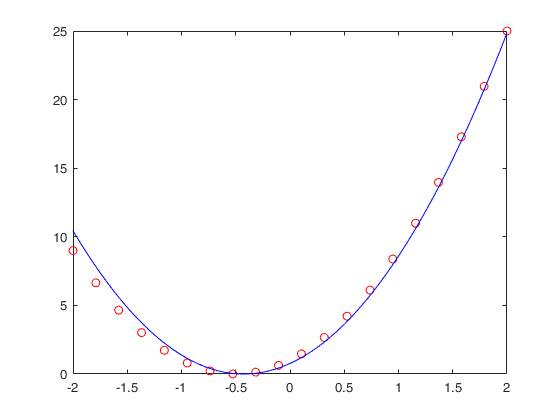

plot(from:((to-from)/(N*10-1)):to,((from:((to-from)/(N*10-1)):to).*w + b).^2,"b-");
hold off;

Vykreslení ztrátové funkce. Můžeme si povšimnout, že ani zde se výpočet nezastavil v lokálnímu minimu, jako tomu bylo u klasické metody BGD bez použití momentu. Metoda je navíc velmi rychlá.